# This exercise is to in-sample estimate volatility via different methods

We use the in-sample information for forrcast.

clc,clear
addpath("Functions/")

## S&P 500

datatable=readtable("SP500_0608.xlsx");
results_folder='Results_SP';
index=datatable.Date>=datetime(2012,05,18)&datatable.Date<datetime(2015,05,18);
rv=datatable.RV(index);
[~,~]=mkdir(results_folder); 
Timeline_insample=datatable.Date(index);
addpath(results_folder);

HAR

J=zeros(size(datatable.RV(index)));
    index_J=(datatable.RV(index)-datatable.RBP(index))>0;
    J(index_J) = log(datatable.RV(index_J)-datatable.RBP(index_J)+1);
vt=log(datatable.RV(index)); % log RV
vt_1=vt(1:end-1);
vt_5=movmean(vt_1,5,'Endpoints','discard');
vt_22=movmean(vt_1,22,'Endpoints','discard');
rt_1=datatable.Return(index);
    rt_1=rt_1(1:end-1);
rvt_1=datatable.RV(index); % RV
    rvt_1=rvt_1(1:end-1);
a1=abs(rt_1)./sqrt(rvt_1);
a2=a1;a2(rt_1>0)=0;
y=vt(23:end);
x0=ones(size(vt_22));
x1=vt_1(22:end);
x2=vt_5(18:end);
x3=vt_22;
x4=J(22:end-1);
x5=a1(22:end);
x6=a2(22:end);

Symmetric HAR

lm=fitlm([x1,x2,x3],y)

lm = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     -2.7768     0.57683     -4.814     1.801e-06
    x1              0.43463    0.042377     10.256    3.8427e-23
    x2              0.28736    0.064446      4.459    9.5396e-06
    x3             0.019568    0.068321    0.28641       0.77465


Number of observations: 730, Error degrees of freedom: 726
Root Mean Squared Error: 0.611
R-squared: 0.383,  Adjusted R-Squared: 0.381
F-statistic vs. constant model: 151, p-value = 7.63e-76

v_HAR=exp([x0 x1 x2 x3]*lm.Coefficients.Estimate);
mean(abs(exp(y)-v_HAR))

ans = 1.3614e-05

sqrt(mean((exp(y)-v_HAR).^2))

ans = 2.3016e-05


[LB,J,~]=Fisher_div_sqr(exp(y),100);
K = OptimalClusterNumber(exp(y),LB);
[v_CPrv,Nodes]=Vol_ClusterPartition(exp(y),K,J);

v_CPHAR = Vol_ClusterPartitionHAR(Nodes,y,v_CPrv, ...
    [x1,x2,x3],100);

mean(abs(exp(y)-v_CPHAR))

ans = 1.3342e-05

sqrt(mean((exp(y)-v_CPHAR).^2))

ans = 2.2231e-05

Asymmetric HAR

lm=fitlm([x1,x2,x3,x4,x5,x6],y)

lm = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6

Estimated Coefficients:
                    Estimate         SE         tStat        pValue  
                   ___________    ________    _________    __________

    (Intercept)        -2.8167      0.5649      -4.9862    7.7149e-07
    x1                 0.33075    0.047544       6.9567    7.8135e-12
    x2                 0.36128    0.066815       5.4072    8.7075e-08
    x3                 0.05447    0.067055      0.81232       0.41687
    x4                  77.185      71.704       1.0764       0.28209
    x5             -0.00049536    0.026866    -0.018438       0.98529
    x6                 0.21824    0.038398       5.6837    1.9123e-08


Number of observa

v_HAR_a=exp([x0 x1 x2 x3 x4 x5 x6]*lm.Coefficients.Estimate);
mean(abs(exp(y)-v_HAR_a))

ans = 1.3136e-05

sqrt(mean((exp(y)-v_HAR_a).^2))

ans = 2.2619e-05


v_CPHAR_a = Vol_ClusterPartitionHAR(Nodes,y,v_CPrv, ...
    [x1,x2,x3,x4,x5,x6],100);

mean(abs(exp(y)-v_CPHAR_a))

ans = 1.2746e-05

sqrt(mean((exp(y)-v_CPHAR_a).^2))

ans = 2.1790e-05

Return

ret=datatable.Return(index);

ARCH test

[h,pValue,stat,cValue] = archtest(ret,'Alpha',[0.01; 0.05; 0.1]);  % Engle test for residual heteroscedasticity
pValue=roundn(pValue,-2);stat=roundn(stat,-2);cValue=roundn(cValue,-2);
table(h,pValue,stat,cValue)

ans = 3×4 table
      h      pValue    stat    cValue
    _____    ______    ____    ______

    false     0.03     4.77     6.63 
    true      0.03     4.77     3.84 
    true      0.03     4.77     2.71 


GARCH

Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
EstMdl = estimate(Mdl,ret);

 
    GARCH(1,1) Conditional Variance Model with Offset (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    7.4942e-06     1.1473e-06        6.5318      6.5002e-11
    GARCH{1}       0.71007       0.055852        12.713      4.9845e-37
    ARCH{1}        0.16354       0.042367          3.86       0.0001134
    Offset      0.00080068     0.00025091        3.1911       0.0014175



v_GARCH=infer(EstMdl,ret);
[LB,J,~]=Fisher_div_sqr(v_GARCH,100);
K = OptimalClusterNumber(v_GARCH,LB);
[v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
v_CPGARCHiteration = Vol_ClusterPartitionIterationGarchorGjr(Nodes,ret,v_CPGARCH,EstMdl,100);

GJR-GARCH

Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN,'Leverage',NaN);
EstMdl = estimate(Mdl,ret);

 
    GJR(1,1) Conditional Variance Model with Offset (Gaussian Distribution):
 
                     Value       StandardError    TStatistic      PValue  
                   __________    _____________    __________    __________

    Constant        5.147e-06     1.7398e-06          2.9584     0.0030929
    GARCH{1}          0.75823       0.040017          18.948    4.6304e-80
    ARCH{1}             2e-12       0.030682      6.5185e-11             1
    Leverage{1}       0.32877       0.063154          5.2058    1.9311e-07
    Offset         0.00045187     0.00025154          1.7964      0.072434



v_GJRGARCH = infer(EstMdl,ret);
[LB,J,~]=Fisher_div_sqr(v_GJRGARCH,5);
K = OptimalClusterNumber(v_GJRGARCH,LB);
[v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
v_CPGJRGARCHiteration = Vol_ClusterPartitionIterationGarchorGjr(Nodes,ret,v_CPGJRGARCH,EstMdl,100);

RSGARCH

% itinial value of RSGARCH
Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN,'Distribution','Gaussian');
EstMdl=estimate(Mdl,ret,'Display','off');
addpath("Functions/m_Files_swgarch")
Mdl_RSGARCH.k=2;
Mdl_RSGARCH.innovation='NORMAL';
Mdl_RSGARCH.model='HAAS';
Mdl_RSGARCH.constraint='CONS';
Mdl_RSGARCH.startvalopt={'YES',[]};
Mdl_RSGARCH.startvalG=[EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1};EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1}];
Mdl_RSGARCH.startvalM=[0.8 0.2;0.2 0.8];
Mdl_RSGARCH.fig=0;
Mdl_RSGARCH.dep_type='INDEP';
estimation = swgarch(ret, Mdl_RSGARCH.k, Mdl_RSGARCH.innovation, Mdl_RSGARCH.model,...
    Mdl_RSGARCH.constraint, Mdl_RSGARCH.startvalopt, Mdl_RSGARCH.startvalG,...
    Mdl_RSGARCH.startvalM,[],[]);

The starting values option and the starting values are not coherent. The estimation continues with random starting values.

v_RSGARCH=estimation.H(2:end);
estimation.garch

ans =     0.0000    0.1713    0.6484
    0.2179    0.3176    0.0344


estimation.transM

ans =     1.0000    0.4350
    0.0000    0.5650


[LB,J,~]=Fisher_div_sqr(v_RSGARCH,100);
K = OptimalClusterNumber(v_RSGARCH,LB);
[v_CPRSGARCH,Nodes]=Vol_ClusterPartition(v_RSGARCH,K,J);
v_CPRSGARCHiteration = Vol_ClusterPartitionIterationRSGARCH(Nodes,ret,v_CPRSGARCH,Mdl_RSGARCH,100);
rmpath("Functions/m_Files_swgarch")
mean(abs(v_RSGARCH-rv))

ans = 3.2849e-05

mean(abs(v_CPRSGARCH-rv))

ans = 3.4337e-05

mean(abs(v_CPRSGARCHiteration-rv))

ans = 3.5772e-05

[LB,J,~]=Fisher_div_sqr(v_GARCH,100);
K1 = OptimalClusterNumber(v_GARCH,LB)

K1 = 4

[~,Nodes1]=Vol_ClusterPartition(v_GARCH,K1,J);
Nodes1

Nodes1 =      1
   133
   485
   593


[LB,J,~]=Fisher_div_sqr(v_GJRGARCH,100);
K2 = OptimalClusterNumber(v_GJRGARCH,LB)

K2 = 5

[~,Nodes2]=Vol_ClusterPartition(v_GJRGARCH,K2,J);
Nodes2

Nodes2 =      1
   284
   391
   491
   593


[LB,J,~]=Fisher_div_sqr(v_RSGARCH,100);
K3 = OptimalClusterNumber(v_RSGARCH,LB)

K3 = 4

[~,Nodes3]=Vol_ClusterPartition(v_RSGARCH,K3,J);
Nodes3

Nodes3 =      1
   162
   484
   593


[LB,J,~]=Fisher_div_sqr(datatable.Return(index).^2,100);
K4 = OptimalClusterNumber(datatable.Return(index).^2,LB)

K4 = 3

[~,Nodes4]=Vol_ClusterPartition(datatable.Return(index).^2,K4,J);
Nodes4

Nodes4 =      1
   278
   591


[LB,J,~]=Fisher_div_sqr(rv,100);
K5 = OptimalClusterNumber(rv,LB)

K5 = 3

[~,Nodes5]=Vol_ClusterPartition(rv,K5,J);
Nodes5

Nodes5 =      1
   284
   592


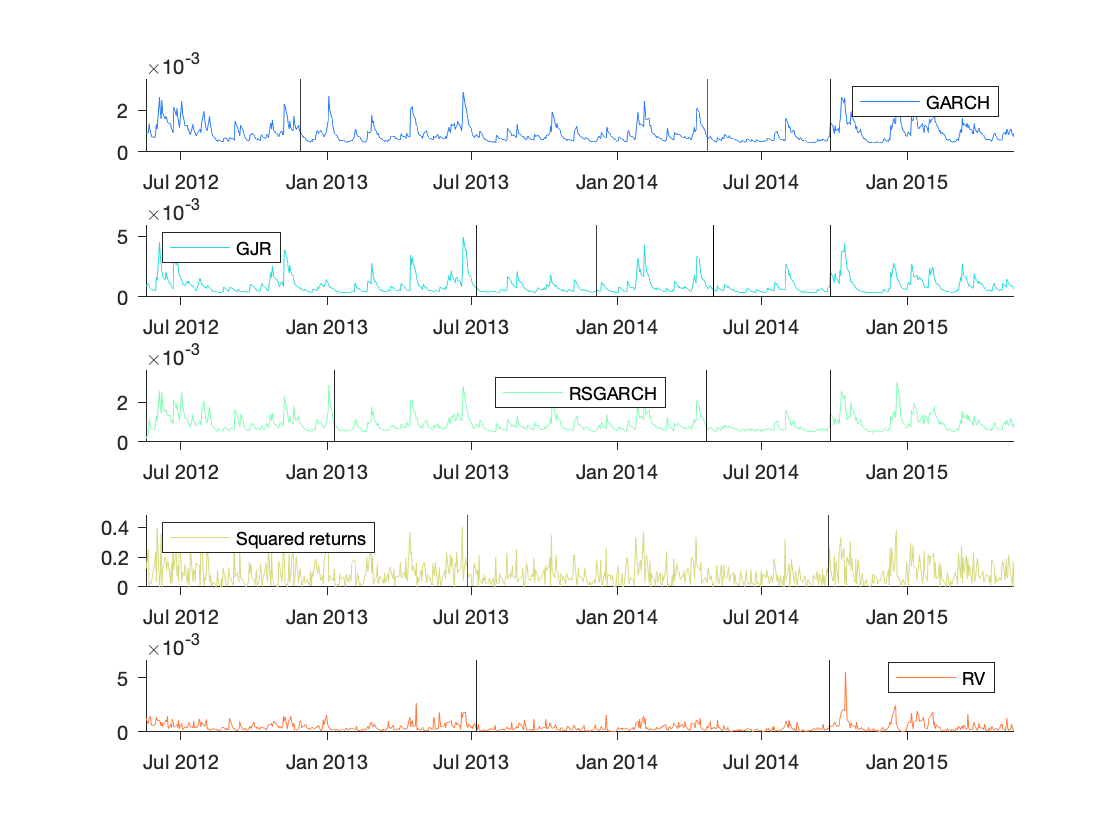

figure;
col=rainbow(5);
subplot(5,1,1);
    plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));
    xlim([Timeline_insample(1),Timeline_insample(end)])
    ylim([0,max(v_GARCH*sqrt(250))*1.2])
    hold on
    for i=2:length(Nodes1)
        plot([Timeline_insample(Nodes1(i)),Timeline_insample(Nodes1(i))],[0,max(v_GARCH*sqrt(250))*1.5],'k')
    end
    legend("GARCH","Location","northeast");
    set(gca,'TickDir','out','Layer','bottom')
    box off
subplot(5,1,2);
    plot(Timeline_insample,v_GJRGARCH*sqrt(250), "Color",col(2,:));
    xlim([Timeline_insample(1),Timeline_insample(end)])
    ylim([0,max(v_GJRGARCH*sqrt(250))*1.2])
    hold on
    for i=2:length(Nodes2)
        plot([Timeline_insample(Nodes2(i)),Timeline_insample(Nodes2(i))],[0,max(v_GJRGARCH*sqrt(250))*1.5],'k')
    end
    legend("GJR","Location","northwest");
    set(gca,'TickDir','out','Layer','bottom')
    box off
subplot(5,1,3);
    plot(Timeline_insample,v_RSGARCH*sqrt(250), "Color",col(3,:));
    xlim([Timeline_insample(1),Timeline_insample(end)])
    ylim([0,max(v_RSGARCH*sqrt(250))*1.2])
    hold on
    for i=2:length(Nodes3)
        plot([Timeline_insample(Nodes3(i)),Timeline_insample(Nodes3(i))],[0,max(v_RSGARCH*sqrt(250))*1.5],'k')
    end
    legend("RSGARCH","Location","north");
    set(gca,'TickDir','out','Layer','bottom')
    box off
subplot(5,1,4);
    plot(Timeline_insample,abs(datatable.Return(index))*sqrt(250), "Color",col(4,:));
    xlim([Timeline_insample(1),Timeline_insample(end)])
    ylim([0,max(abs(datatable.Return(index)))*sqrt(250)*1.2])
    hold on
    for i=2:length(Nodes4)
        plot([Timeline_insample(Nodes4(i)),Timeline_insample(Nodes4(i))],[0,max(abs(datatable.Return(index))*sqrt(250))*1.5],'k')
    end
    legend("Squared returns","Location","northwest");
    set(gca,'TickDir','out','Layer','bottom')
    box off
subplot(5,1,5);
    plot(Timeline_insample,rv*sqrt(250), "Color",col(5,:));
    xlim([Timeline_insample(1),Timeline_insample(end)])
    ylim([0,max(rv)*sqrt(250)*1.2])
    hold on
    for i=2:length(Nodes5)
    plot([Timeline_insample(Nodes5(i)),Timeline_insample(Nodes5(i))],[0,max(rv*sqrt(250))*1.5],'k')
    end
    legend("RV","Location","best");
    set(gca,'TickDir','out','Layer','bottom')
    box off
saveas(gcf,[results_folder,'/Volatility_CP_GARCH_GJR_RSGARCH.png'])

MAE=[mean(abs(v_GARCH-rv));mean(abs(v_CPGARCH-rv));mean(abs(v_CPGARCHiteration-rv))
    mean(abs(v_GJRGARCH-rv));mean(abs(v_CPGJRGARCH-rv));mean(abs(v_CPGJRGARCHiteration-rv))
    mean(abs(v_RSGARCH-rv));mean(abs(v_CPRSGARCH-rv));mean(abs(v_CPRSGARCHiteration-rv))
    mean(abs(v_HAR-rv(23:end)));mean(abs(v_HAR_a-rv(23:end)))
    mean(abs(v_CPHAR-rv(23:end)));mean(abs(v_CPHAR_a-rv(23:end)))]*sqrt(250)*1000;
RMSE=sqrt([mean((v_GARCH-rv).^2);mean((v_CPGARCH-rv).^2);mean((v_CPGARCHiteration-rv).^2)
    mean((v_GJRGARCH-rv).^2);mean((v_CPGJRGARCH-rv).^2);mean((v_CPGJRGARCHiteration-rv).^2)
    mean((v_RSGARCH-rv).^2);mean((v_CPRSGARCH-rv).^2);mean((v_CPRSGARCHiteration-rv).^2)
    mean((v_HAR-rv(23:end)).^2);mean((v_HAR_a-rv(23:end)).^2) 
    mean((v_CPHAR-rv(23:end)).^2);mean((v_CPHAR_a-rv(23:end)).^2)])*sqrt(250)*1000;
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.',...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH', 'CPRSGARCH', 'CPRSGARCH Ite.', 'HAR', 'HAR_a', 'CPHAR', 'CPHAR_a'})

ans = 13×2 table
                         MAE       RMSE  
                       _______    _______

    GARCH              0.50308    0.62278
    CPGARCH            0.53442    0.60775
    GARCH Ite.         0.53317    0.60685
    GJRGARCH            0.5395    0.75989
    CPGJRGARCH         0.53776    0.72676
    CPGJRGARCH Ite.    0.56218    0.63844
    RSGARCH            0.51939    0.63329
    CPRSGARCH          0.54292    0.61394
    CPRSGARCH Ite.      0.5656    0.66375
    HAR                0.21526    0.36392
    HAR_a              0.20769    0.35763
    CPHAR              0.21096     0.3515
    CPHAR_a            0.20154    0.34453


## DAX 30

datatable=readtable("DAX_0608.xlsx");
results_folder='Results_DAX';
index=datatable.Date>=datetime(2012,05,18)&datatable.Date<datetime(2015,05,18);
rv=datatable.RV(index);
[~,~]=mkdir(results_folder); 
Timeline_insample=datatable.Date(index);
addpath(results_folder);

HAR

J=zeros(size(datatable.RV(index)));
    index_J=(datatable.RV(index)-datatable.RBP(index))>0;
    J(index_J) = log(datatable.RV(index_J)-datatable.RBP(index_J)+1);
vt=log(datatable.RV(index)); % log RV
vt_1=vt(1:end-1);
vt_5=movmean(vt_1,5,'Endpoints','discard');
vt_22=movmean(vt_1,22,'Endpoints','discard');
rt_1=datatable.Return(index);
    rt_1=rt_1(1:end-1);
rvt_1=datatable.RV(index); % RV
    rvt_1=rvt_1(1:end-1);
a1=abs(rt_1)./sqrt(rvt_1);
a2=a1;a2(rt_1>0)=0;
y=vt(23:end);
x0=ones(size(vt_22));
x1=vt_1(22:end);
x2=vt_5(18:end);
x3=vt_22;
x4=J(22:end-1);
x5=a1(22:end);
x6=a2(22:end);

Symmetric HAR

lm=fitlm([x1,x2,x3],y)

lm = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     -1.7246     0.45225    -3.8135    0.00014862
    x1              0.23894    0.043269     5.5222    4.6568e-08
    x2              0.52277    0.070447     7.4208    3.2442e-13
    x3             0.061562    0.068941    0.89297       0.37217


Number of observations: 734, Error degrees of freedom: 730
Root Mean Squared Error: 0.551
R-squared: 0.403,  Adjusted R-Squared: 0.4
F-statistic vs. constant model: 164, p-value = 3e-81

v_HAR=exp([x0 x1 x2 x3]*lm.Coefficients.Estimate);
mean(abs(exp(y)-v_HAR))

ans = 3.1339e-05

sqrt(mean((exp(y)-v_HAR).^2))

ans = 5.3054e-05


[LB,J,~]=Fisher_div_sqr(exp(y),100);
K = OptimalClusterNumber(exp(y),LB);
[v_CPrv,Nodes]=Vol_ClusterPartition(exp(y),K,J);

v_CPHAR = Vol_ClusterPartitionHAR(Nodes,y,v_CPrv, ...
    [x1,x2,x3],100);

mean(abs(exp(y)-v_CPHAR))

ans = 3.0582e-05

sqrt(mean((exp(y)-v_CPHAR).^2))

ans = 5.1750e-05

Asymmetric HAR

lm=fitlm([x1,x2,x3,x4,x5,x6],y)

lm = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6

Estimated Coefficients:
                   Estimate        SE        tStat       pValue  
                   _________    ________    _______    __________

    (Intercept)      -1.6781     0.44051    -3.8094    0.00015107
    x1               0.13061    0.045019     2.9012       0.00383
    x2                0.6168    0.070069     8.8027    9.6647e-18
    x3              0.084835    0.067175     1.2629       0.20703
    x4                723.95      672.53     1.0765       0.28208
    x5             -0.062686    0.026685    -2.3491      0.019086
    x6               0.24146    0.036108     6.6872     4.537e-11


Number of observations: 734, Error degrees of freedom

v_HAR_a=exp([x0 x1 x2 x3 x4 x5 x6]*lm.Coefficients.Estimate);
mean(abs(exp(y)-v_HAR_a))

ans = 3.0383e-05

sqrt(mean((exp(y)-v_HAR_a).^2))

ans = 5.1546e-05


v_CPHAR_a = Vol_ClusterPartitionHAR(Nodes,y,v_CPrv, ...
    [x1,x2,x3,x4,x5,x6],100);

mean(abs(exp(y)-v_CPHAR_a))

ans = 2.9105e-05

sqrt(mean((exp(y)-v_CPHAR_a).^2))

ans = 4.9573e-05

Return

ret=datatable.Return(index);

ARCH test

[h,pValue,stat,cValue] = archtest(ret,'Alpha',[0.01; 0.05; 0.1]);  % Engle test for residual heteroscedasticity
pValue=roundn(pValue,-2);stat=roundn(stat,-2);cValue=roundn(cValue,-2);
table(h,pValue,stat,cValue)

ans = 3×4 table
      h      pValue    stat    cValue
    _____    ______    ____    ______

    false     0.03     4.9      6.63 
    true      0.03     4.9      3.84 
    true      0.03     4.9      2.71 


GARCH

Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
EstMdl = estimate(Mdl,ret);

 
    GARCH(1,1) Conditional Variance Model with Offset (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant    5.0715e-06     2.9418e-06        1.7239          0.08472
    GARCH{1}       0.87052       0.036672        23.738      1.4486e-124
    ARCH{1}        0.08897       0.022081        4.0292       5.5974e-05
    Offset      0.00099499     0.00035529        2.8005         0.005102



v_GARCH=infer(EstMdl,ret);
[LB,J,~]=Fisher_div_sqr(v_GARCH,100);
K = OptimalClusterNumber(v_GARCH,LB);
[v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
v_CPGARCHiteration = Vol_ClusterPartitionIterationGarchorGjr(Nodes,ret,v_CPGARCH,EstMdl,100);

GJR-GARCH

Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN,'Leverage',NaN);
EstMdl = estimate(Mdl,ret);

 
    GJR(1,1) Conditional Variance Model with Offset (Gaussian Distribution):
 
                     Value       StandardError    TStatistic      PValue  
                   __________    _____________    __________    __________

    Constant       6.4446e-06     3.5412e-07          18.199    5.2708e-74
    GARCH{1}          0.85267       0.021318          39.997             0
    ARCH{1}             2e-12       0.019759      1.0122e-10             1
    Leverage{1}       0.18462       0.040985          4.5044    6.6547e-06
    Offset         0.00062469     0.00036187          1.7263      0.084298



v_GJRGARCH = infer(EstMdl,ret);
[LB,J,~]=Fisher_div_sqr(v_GJRGARCH,5);
K = OptimalClusterNumber(v_GJRGARCH,LB);
[v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
v_CPGJRGARCHiteration = Vol_ClusterPartitionIterationGarchorGjr(Nodes,ret,v_CPGJRGARCH,EstMdl,100);

RSGARCH

% itinial value of RSGARCH
Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN,'Distribution','Gaussian');
EstMdl=estimate(Mdl,ret,'Display','off');
addpath("Functions/m_Files_swgarch")
Mdl_RSGARCH.k=2;
Mdl_RSGARCH.innovation='NORMAL';
Mdl_RSGARCH.model='HAAS';
Mdl_RSGARCH.constraint='CONS';
Mdl_RSGARCH.startvalopt={'YES',[]};
Mdl_RSGARCH.startvalG=[EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1};EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1}];
Mdl_RSGARCH.startvalM=[0.8 0.2;0.2 0.8];
Mdl_RSGARCH.fig=0;
Mdl_RSGARCH.dep_type='INDEP';
estimation = swgarch(ret, Mdl_RSGARCH.k, Mdl_RSGARCH.innovation, Mdl_RSGARCH.model,...
    Mdl_RSGARCH.constraint, Mdl_RSGARCH.startvalopt, Mdl_RSGARCH.startvalG,...
    Mdl_RSGARCH.startvalM,[],[]);

The starting values option and the starting values are not coherent. The estimation continues with random starting values.

v_RSGARCH=estimation.H(2:end);
estimation.garch

ans =     0.0000    0.1768    0.7924
    0.0000    0.1087    0.6157


estimation.transM

ans =     0.3409    0.3715
    0.6591    0.6285


[LB,J,~]=Fisher_div_sqr(v_RSGARCH,100);
K = OptimalClusterNumber(v_RSGARCH,LB);
[v_CPRSGARCH,Nodes]=Vol_ClusterPartition(v_RSGARCH,K,J);
v_CPRSGARCHiteration = Vol_ClusterPartitionIterationRSGARCH(Nodes,ret,v_CPRSGARCH,Mdl_RSGARCH,100);
rmpath("Functions/m_Files_swgarch")
mean(abs(v_RSGARCH-rv))

ans = 5.4563e-05

mean(abs(v_CPRSGARCH-rv))

ans = 5.7283e-05

mean(abs(v_CPRSGARCHiteration-rv))

ans = 5.7745e-05

[LB,J,~]=Fisher_div_sqr(v_GARCH,100);
K1 = OptimalClusterNumber(v_GARCH,LB)

K1 = 7

[~,Nodes1]=Vol_ClusterPartition(v_GARCH,K1,J);
Nodes1

Nodes1 =      1
   101
   201
   301
   405
   505
   610


[LB,J,~]=Fisher_div_sqr(v_GJRGARCH,100);
K2 = OptimalClusterNumber(v_GJRGARCH,LB)

K2 = 7

[~,Nodes2]=Vol_ClusterPartition(v_GJRGARCH,K2,J);
Nodes2

Nodes2 =      1
   101
   201
   301
   401
   501
   601


[LB,J,~]=Fisher_div_sqr(v_RSGARCH,100);
K3 = OptimalClusterNumber(v_RSGARCH,LB)

K3 = 7

[~,Nodes3]=Vol_ClusterPartition(v_RSGARCH,K3,J);
Nodes3

Nodes3 =      1
   103
   203
   303
   404
   504
   604


[LB,J,~]=Fisher_div_sqr(datatable.Return(index).^2,100);
K4 = OptimalClusterNumber(datatable.Return(index).^2,LB)

K4 = 3

[~,Nodes4]=Vol_ClusterPartition(datatable.Return(index).^2,K4,J);
Nodes4

Nodes4 =      1
   103
   604


[LB,J,~]=Fisher_div_sqr(rv,100);
K5 = OptimalClusterNumber(rv,LB)

K5 = 5

[~,Nodes5]=Vol_ClusterPartition(rv,K5,J);
Nodes5

Nodes5 =      1
   101
   291
   427
   604


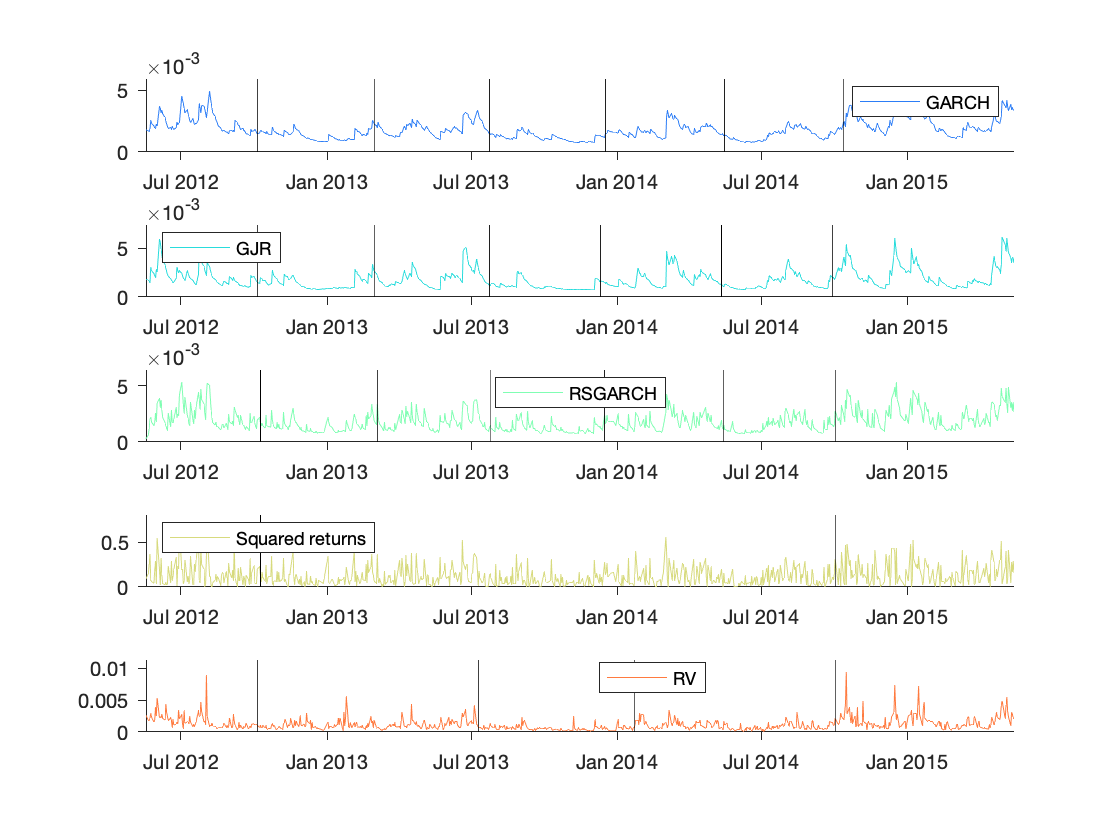

figure;
col=rainbow(5);
subplot(5,1,1);
    plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));
    xlim([Timeline_insample(1),Timeline_insample(end)])
    ylim([0,max(v_GARCH*sqrt(250))*1.2])
    hold on
    for i=2:length(Nodes1)
        plot([Timeline_insample(Nodes1(i)),Timeline_insample(Nodes1(i))],[0,max(v_GARCH*sqrt(250))*1.5],'k')
    end
    legend("GARCH","Location","northeast");
    set(gca,'TickDir','out','Layer','bottom')
    box off
subplot(5,1,2);
    plot(Timeline_insample,v_GJRGARCH*sqrt(250), "Color",col(2,:));
    xlim([Timeline_insample(1),Timeline_insample(end)])
    ylim([0,max(v_GJRGARCH*sqrt(250))*1.2])
    hold on
    for i=2:length(Nodes2)
        plot([Timeline_insample(Nodes2(i)),Timeline_insample(Nodes2(i))],[0,max(v_GJRGARCH*sqrt(250))*1.5],'k')
    end
    legend("GJR","Location","northwest");
    set(gca,'TickDir','out','Layer','bottom')
    box off
subplot(5,1,3);
    plot(Timeline_insample,v_RSGARCH*sqrt(250), "Color",col(3,:));
    xlim([Timeline_insample(1),Timeline_insample(end)])
    ylim([0,max(v_RSGARCH*sqrt(250))*1.2])
    hold on
    for i=2:length(Nodes3)
        plot([Timeline_insample(Nodes3(i)),Timeline_insample(Nodes3(i))],[0,max(v_RSGARCH*sqrt(250))*1.5],'k')
    end
    legend("RSGARCH","Location","north");
    set(gca,'TickDir','out','Layer','bottom')
    box off
subplot(5,1,4);
    plot(Timeline_insample,abs(datatable.Return(index))*sqrt(250), "Color",col(4,:));
    xlim([Timeline_insample(1),Timeline_insample(end)])
    ylim([0,max(abs(datatable.Return(index)))*sqrt(250)*1.2])
    hold on
    for i=2:length(Nodes4)
        plot([Timeline_insample(Nodes4(i)),Timeline_insample(Nodes4(i))],[0,max(abs(datatable.Return(index))*sqrt(250))*1.5],'k')
    end
    legend("Squared returns","Location","northwest");
    set(gca,'TickDir','out','Layer','bottom')
    box off
subplot(5,1,5);
    plot(Timeline_insample,rv*sqrt(250), "Color",col(5,:));
    xlim([Timeline_insample(1),Timeline_insample(end)])
    ylim([0,max(rv)*sqrt(250)*1.2])
    hold on
    for i=2:length(Nodes5)
    plot([Timeline_insample(Nodes5(i)),Timeline_insample(Nodes5(i))],[0,max(rv*sqrt(250))*1.5],'k')
    end
    legend("RV","Location","best");
    set(gca,'TickDir','out','Layer','bottom')
    box off
saveas(gcf,[results_folder,'/Volatility_CP_GARCH_GJR_RSGARCH.png'])

MAE=[mean(abs(v_GARCH-rv));mean(abs(v_CPGARCH-rv));mean(abs(v_CPGARCHiteration-rv))
    mean(abs(v_GJRGARCH-rv));mean(abs(v_CPGJRGARCH-rv));mean(abs(v_CPGJRGARCHiteration-rv))
    mean(abs(v_RSGARCH-rv));mean(abs(v_CPRSGARCH-rv));mean(abs(v_CPRSGARCHiteration-rv))
    mean(abs(v_HAR-rv(23:end)));mean(abs(v_HAR_a-rv(23:end)))
    mean(abs(v_CPHAR-rv(23:end)));mean(abs(v_CPHAR_a-rv(23:end)))]*sqrt(250)*1000;
RMSE=sqrt([mean((v_GARCH-rv).^2);mean((v_CPGARCH-rv).^2);mean((v_CPGARCHiteration-rv).^2)
    mean((v_GJRGARCH-rv).^2);mean((v_CPGJRGARCH-rv).^2);mean((v_CPGJRGARCHiteration-rv).^2)
    mean((v_RSGARCH-rv).^2);mean((v_CPRSGARCH-rv).^2);mean((v_CPRSGARCHiteration-rv).^2)
    mean((v_HAR-rv(23:end)).^2);mean((v_HAR_a-rv(23:end)).^2) 
    mean((v_CPHAR-rv(23:end)).^2);mean((v_CPHAR_a-rv(23:end)).^2)])*sqrt(250)*1000;
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.',...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH', 'CPRSGARCH', 'CPRSGARCH Ite.', 'HAR', 'HAR_a', 'CPHAR', 'CPHAR_a'})

ans = 13×2 table
                         MAE       RMSE  
                       _______    _______

    GARCH              0.86298     1.0937
    CPGARCH            0.90894     1.1169
    GARCH Ite.         0.90539     1.1173
    GJRGARCH           0.84449     1.1135
    CPGJRGARCH         0.84717     1.1054
    CPGJRGARCH Ite.    0.90191     1.1065
    RSGARCH            0.86272     1.1071
    CPRSGARCH          0.90572     1.1071
    CPRSGARCH Ite.     0.91303     1.1616
    HAR                0.49551    0.83886
    HAR_a              0.48039    0.81502
    CPHAR              0.48354    0.81824
    CPHAR_a            0.46019    0.78382


## FTSE 100

datatable=readtable("FTSE_0608.xlsx");
results_folder='Results_FTSE';
index=datatable.Date>=datetime(2012,05,18)&datatable.Date<datetime(2015,05,18);
rv=datatable.RV(index);
[~,~]=mkdir(results_folder); 
Timeline_insample=datatable.Date(index);
addpath(results_folder);

HAR

J=zeros(size(datatable.RV(index)));
    index_J=(datatable.RV(index)-datatable.RBP(index))>0;
    J(index_J) = log(datatable.RV(index_J)-datatable.RBP(index_J)+1);
vt=log(datatable.RV(index)); % log RV
vt_1=vt(1:end-1);
vt_5=movmean(vt_1,5,'Endpoints','discard');
vt_22=movmean(vt_1,22,'Endpoints','discard');
rt_1=datatable.Return(index);
    rt_1=rt_1(1:end-1);
rvt_1=datatable.RV(index); % RV
    rvt_1=rvt_1(1:end-1);
a1=abs(rt_1)./sqrt(rvt_1);
a2=a1;a2(rt_1>0)=0;
y=vt(23:end);
x0=ones(size(vt_22));
x1=vt_1(22:end);
x2=vt_5(18:end);
x3=vt_22;
x4=J(22:end-1);
x5=a1(22:end);
x6=a2(22:end);

Symmetric HAR

lm=fitlm([x1,x2,x3],y)

lm = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     -1.6601     0.42377    -3.9176    9.7848e-05
    x1              0.28158    0.044315     6.3539    3.6936e-10
    x2              0.47992    0.070065     6.8496    1.5736e-11
    x3             0.079609    0.063045     1.2627       0.20709


Number of observations: 734, Error degrees of freedom: 730
Root Mean Squared Error: 0.457
R-squared: 0.456,  Adjusted R-Squared: 0.454
F-statistic vs. constant model: 204, p-value = 4.37e-96

v_HAR=exp([x0 x1 x2 x3]*lm.Coefficients.Estimate);
mean(abs(exp(y)-v_HAR))

ans = 1.2868e-05

sqrt(mean((exp(y)-v_HAR).^2))

ans = 2.2276e-05


[LB,J,~]=Fisher_div_sqr(exp(y),100);
K = OptimalClusterNumber(exp(y),LB);
[v_CPrv,Nodes]=Vol_ClusterPartition(exp(y),K,J);

v_CPHAR = Vol_ClusterPartitionHAR(Nodes,y,v_CPrv, ...
    [x1,x2,x3],100);

mean(abs(exp(y)-v_CPHAR))

ans = 1.2536e-05

sqrt(mean((exp(y)-v_CPHAR).^2))

ans = 2.1634e-05

Asymmetric HAR

lm=fitlm([x1,x2,x3,x4,x5,x6],y)

lm = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6

Estimated Coefficients:
                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)      -1.6301     0.41864     -3.8938    0.00010775
    x1                0.1942    0.046818       4.148    3.7503e-05
    x2                0.5502    0.070742      7.7774    2.5373e-14
    x3               0.10335    0.062244      1.6603      0.097278
    x4               -1841.5      1728.8     -1.0651       0.28716
    x5             -0.020075    0.023899    -0.83996       0.40121
    x6               0.15095    0.029157      5.1771    2.9198e-07


Number of observations: 734, Error degrees o

v_HAR_a=exp([x0 x1 x2 x3 x4 x5 x6]*lm.Coefficients.Estimate);
mean(abs(exp(y)-v_HAR_a))

ans = 1.2590e-05

sqrt(mean((exp(y)-v_HAR_a).^2))

ans = 2.1791e-05


v_CPHAR_a = Vol_ClusterPartitionHAR(Nodes,y,v_CPrv, ...
    [x1,x2,x3,x4,x5,x6],100);

mean(abs(exp(y)-v_CPHAR_a))

ans = 1.2188e-05

sqrt(mean((exp(y)-v_CPHAR_a).^2))

ans = 2.0677e-05

Return

ret=datatable.Return(index);

ARCH test

[h,pValue,stat,cValue] = archtest(ret,'Alpha',[0.01; 0.05; 0.1]);  % Engle test for residual heteroscedasticity
pValue=roundn(pValue,-2);stat=roundn(stat,-2);cValue=roundn(cValue,-2);
table(h,pValue,stat,cValue)

ans = 3×4 table
      h      pValue    stat    cValue
    _____    ______    ____    ______

    true      0.01     7.77     6.63 
    true      0.01     7.77     3.84 
    true      0.01     7.77     2.71 


GARCH

Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
EstMdl = estimate(Mdl,ret);

 
    GARCH(1,1) Conditional Variance Model with Offset (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant    5.0693e-06     1.6426e-06        3.0861        0.0020281
    GARCH{1}       0.79555       0.032972        24.128      1.2792e-128
    ARCH{1}        0.12391       0.025901        4.7839       1.7189e-06
    Offset      0.00047902      0.0002433        1.9688         0.048973



v_GARCH=infer(EstMdl,ret);
[LB,J,~]=Fisher_div_sqr(v_GARCH,100);
K = OptimalClusterNumber(v_GARCH,LB);
[v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
v_CPGARCHiteration = Vol_ClusterPartitionIterationGarchorGjr(Nodes,ret,v_CPGARCH,EstMdl,100);

GJR-GARCH

Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN,'Leverage',NaN);
EstMdl = estimate(Mdl,ret);

 
    GJR(1,1) Conditional Variance Model with Offset (Gaussian Distribution):
 
                     Value       StandardError    TStatistic      PValue   
                   __________    _____________    __________    ___________

    Constant       4.7657e-06     1.2712e-06          3.7491     0.00017751
    GARCH{1}          0.79724       0.026109          30.535    9.0519e-205
    ARCH{1}             2e-12        0.02455      8.1467e-11              1
    Leverage{1}       0.25836       0.046134          5.6002     2.1415e-08
    Offset         0.00017673     0.00025383         0.69626        0.48627



v_GJRGARCH = infer(EstMdl,ret);
[LB,J,~]=Fisher_div_sqr(v_GJRGARCH,5);
K = OptimalClusterNumber(v_GJRGARCH,LB);
[v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
v_CPGJRGARCHiteration = Vol_ClusterPartitionIterationGarchorGjr(Nodes,ret,v_CPGJRGARCH,EstMdl,100);

RSGARCH

% itinial value of RSGARCH
Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN,'Distribution','Gaussian');
EstMdl=estimate(Mdl,ret,'Display','off');
addpath("Functions/m_Files_swgarch")
Mdl_RSGARCH.k=2;
Mdl_RSGARCH.innovation='NORMAL';
Mdl_RSGARCH.model='HAAS';
Mdl_RSGARCH.constraint='CONS';
Mdl_RSGARCH.startvalopt={'YES',[]};
Mdl_RSGARCH.startvalG=[EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1};EstMdl.Constant,EstMdl.ARCH{1},EstMdl.GARCH{1}];
Mdl_RSGARCH.startvalM=[0.8 0.2;0.2 0.8];
Mdl_RSGARCH.fig=0;
Mdl_RSGARCH.dep_type='INDEP';
estimation = swgarch(ret, Mdl_RSGARCH.k, Mdl_RSGARCH.innovation, Mdl_RSGARCH.model,...
    Mdl_RSGARCH.constraint, Mdl_RSGARCH.startvalopt, Mdl_RSGARCH.startvalG,...
    Mdl_RSGARCH.startvalM,[],[]);

The starting values option and the starting values are not coherent. The estimation continues with random starting values.

v_RSGARCH=estimation.H(2:end);
estimation.garch

ans =     0.0000    0.2748    0.5984
    0.0000    0.1568    0.4664


estimation.transM

ans =     0.3092    0.2898
    0.6908    0.7102


[LB,J,~]=Fisher_div_sqr(v_RSGARCH,100);
K = OptimalClusterNumber(v_RSGARCH,LB);
[v_CPRSGARCH,Nodes]=Vol_ClusterPartition(v_RSGARCH,K,J);
v_CPRSGARCHiteration = Vol_ClusterPartitionIterationRSGARCH(Nodes,ret,v_CPRSGARCH,Mdl_RSGARCH,100);
rmpath("Functions/m_Files_swgarch")
mean(abs(v_RSGARCH-rv))

ans = 2.9939e-05

mean(abs(v_CPRSGARCH-rv))

ans = 3.1617e-05

mean(abs(v_CPRSGARCHiteration-rv))

ans = 3.0234e-05

[LB,J,~]=Fisher_div_sqr(v_GARCH,100);
K1 = OptimalClusterNumber(v_GARCH,LB)

K1 = 6

[~,Nodes1]=Vol_ClusterPartition(v_GARCH,K1,J);
Nodes1

Nodes1 =      1
   101
   223
   331
   491
   602


[LB,J,~]=Fisher_div_sqr(v_GJRGARCH,100);
K2 = OptimalClusterNumber(v_GJRGARCH,LB)

K2 = 5

[~,Nodes2]=Vol_ClusterPartition(v_GJRGARCH,K2,J);
Nodes2

Nodes2 =      1
   134
   257
   357
   595


[LB,J,~]=Fisher_div_sqr(v_RSGARCH,100);
K3 = OptimalClusterNumber(v_RSGARCH,LB)

K3 = 6

[~,Nodes3]=Vol_ClusterPartition(v_RSGARCH,K3,J);
Nodes3

Nodes3 =      1
   101
   220
   329
   489
   594


[LB,J,~]=Fisher_div_sqr(datatable.Return(index).^2,100);
K4 = OptimalClusterNumber(datatable.Return(index).^2,LB)

K4 = 3

[~,Nodes4]=Vol_ClusterPartition(datatable.Return(index).^2,K4,J);
Nodes4

Nodes4 =      1
   289
   593


[LB,J,~]=Fisher_div_sqr(rv,100);
K5 = OptimalClusterNumber(rv,LB)

K5 = 6

[~,Nodes5]=Vol_ClusterPartition(rv,K5,J);
Nodes5

Nodes5 =      1
   101
   211
   331
   487
   601


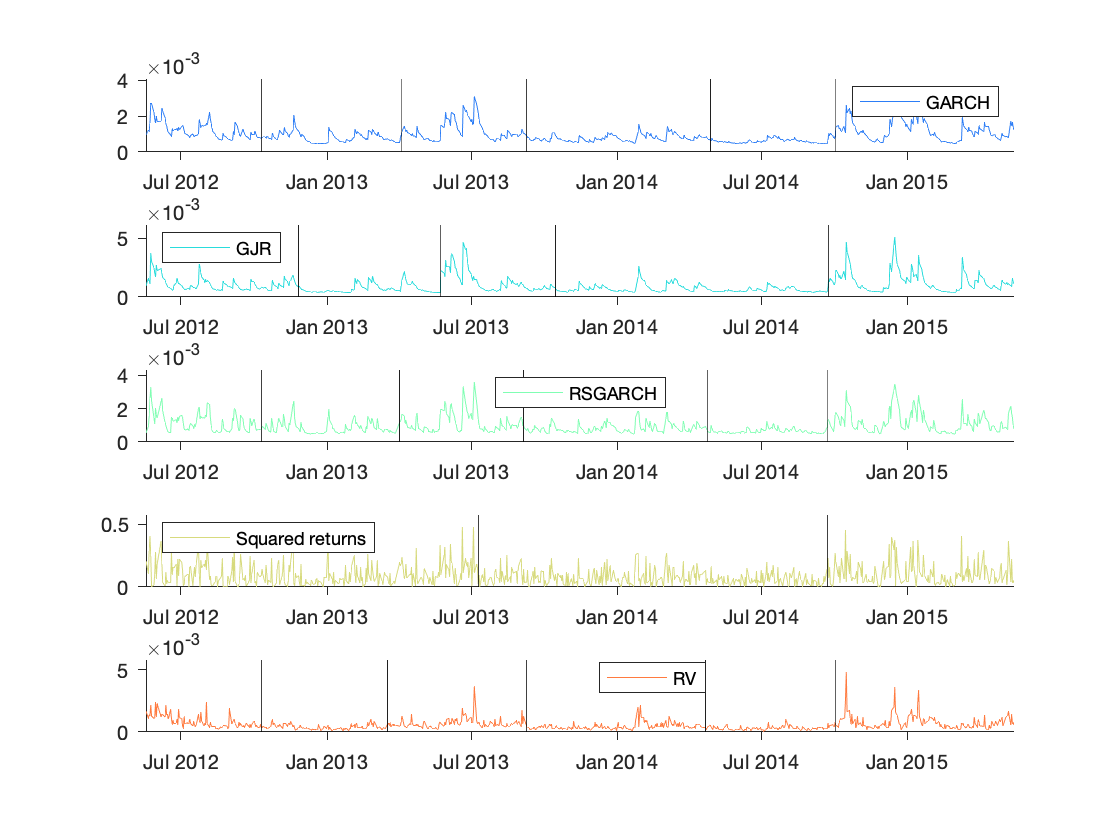

figure;
col=rainbow(5);
subplot(5,1,1);
    plot(Timeline_insample,v_GARCH*sqrt(250), "Color",col(1,:));
    xlim([Timeline_insample(1),Timeline_insample(end)])
    ylim([0,max(v_GARCH*sqrt(250))*1.2])
    hold on
    for i=2:length(Nodes1)
        plot([Timeline_insample(Nodes1(i)),Timeline_insample(Nodes1(i))],[0,max(v_GARCH*sqrt(250))*1.5],'k')
    end
    legend("GARCH","Location","northeast");
    set(gca,'TickDir','out','Layer','bottom')
    box off
subplot(5,1,2);
    plot(Timeline_insample,v_GJRGARCH*sqrt(250), "Color",col(2,:));
    xlim([Timeline_insample(1),Timeline_insample(end)])
    ylim([0,max(v_GJRGARCH*sqrt(250))*1.2])
    hold on
    for i=2:length(Nodes2)
        plot([Timeline_insample(Nodes2(i)),Timeline_insample(Nodes2(i))],[0,max(v_GJRGARCH*sqrt(250))*1.5],'k')
    end
    legend("GJR","Location","northwest");
    set(gca,'TickDir','out','Layer','bottom')
    box off
subplot(5,1,3);
    plot(Timeline_insample,v_RSGARCH*sqrt(250), "Color",col(3,:));
    xlim([Timeline_insample(1),Timeline_insample(end)])
    ylim([0,max(v_RSGARCH*sqrt(250))*1.2])
    hold on
    for i=2:length(Nodes3)
        plot([Timeline_insample(Nodes3(i)),Timeline_insample(Nodes3(i))],[0,max(v_RSGARCH*sqrt(250))*1.5],'k')
    end
    legend("RSGARCH","Location","north");
    set(gca,'TickDir','out','Layer','bottom')
    box off
subplot(5,1,4);
    plot(Timeline_insample,abs(datatable.Return(index))*sqrt(250), "Color",col(4,:));
    xlim([Timeline_insample(1),Timeline_insample(end)])
    ylim([0,max(abs(datatable.Return(index)))*sqrt(250)*1.2])
    hold on
    for i=2:length(Nodes4)
        plot([Timeline_insample(Nodes4(i)),Timeline_insample(Nodes4(i))],[0,max(abs(datatable.Return(index))*sqrt(250))*1.5],'k')
    end
    legend("Squared returns","Location","northwest");
    set(gca,'TickDir','out','Layer','bottom')
    box off
subplot(5,1,5);
    plot(Timeline_insample,rv*sqrt(250), "Color",col(5,:));
    xlim([Timeline_insample(1),Timeline_insample(end)])
    ylim([0,max(rv)*sqrt(250)*1.2])
    hold on
    for i=2:length(Nodes5)
    plot([Timeline_insample(Nodes5(i)),Timeline_insample(Nodes5(i))],[0,max(rv*sqrt(250))*1.5],'k')
    end
    legend("RV","Location","best");
    set(gca,'TickDir','out','Layer','bottom')
    box off
saveas(gcf,[results_folder,'/Volatility_CP_GARCH_GJR_RSGARCH.png'])

MAE=[mean(abs(v_GARCH-rv));mean(abs(v_CPGARCH-rv));mean(abs(v_CPGARCHiteration-rv))
    mean(abs(v_GJRGARCH-rv));mean(abs(v_CPGJRGARCH-rv));mean(abs(v_CPGJRGARCHiteration-rv))
    mean(abs(v_RSGARCH-rv));mean(abs(v_CPRSGARCH-rv));mean(abs(v_CPRSGARCHiteration-rv))
    mean(abs(v_HAR-rv(23:end)));mean(abs(v_HAR_a-rv(23:end)))
    mean(abs(v_CPHAR-rv(23:end)));mean(abs(v_CPHAR_a-rv(23:end)))]*sqrt(250)*1000;
RMSE=sqrt([mean((v_GARCH-rv).^2);mean((v_CPGARCH-rv).^2);mean((v_CPGARCHiteration-rv).^2)
    mean((v_GJRGARCH-rv).^2);mean((v_CPGJRGARCH-rv).^2);mean((v_CPGJRGARCHiteration-rv).^2)
    mean((v_RSGARCH-rv).^2);mean((v_CPRSGARCH-rv).^2);mean((v_CPRSGARCHiteration-rv).^2)
    mean((v_HAR-rv(23:end)).^2);mean((v_HAR_a-rv(23:end)).^2) 
    mean((v_CPHAR-rv(23:end)).^2);mean((v_CPHAR_a-rv(23:end)).^2)])*sqrt(250)*1000;
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.',...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH', 'CPRSGARCH', 'CPRSGARCH Ite.', 'HAR', 'HAR_a', 'CPHAR', 'CPHAR_a'})

ans = 13×2 table
                         MAE       RMSE  
                       _______    _______

    GARCH              0.45916    0.57442
    CPGARCH            0.47903    0.56503
    GARCH Ite.         0.48047    0.56746
    GJRGARCH           0.48048    0.68572
    CPGJRGARCH         0.47156     0.6638
    CPGJRGARCH Ite.    0.49107    0.58219
    RSGARCH            0.47338    0.59133
    CPRSGARCH          0.49991    0.57763
    CPRSGARCH Ite.     0.47804    0.60127
    HAR                0.20346    0.35221
    HAR_a              0.19906    0.34454
    CPHAR              0.19822    0.34206
    CPHAR_a            0.19271    0.32694


### Summary statistics

sp=readtable("SP500_0608.xlsx");
dax=readtable("DAX_0608.xlsx");
ftse=readtable("FTSE_0608.xlsx");
summ_stats=nan(3,4);
summ_stats(1,1:6)=[252*mean(sp.Return)*100,sqrt(252)*std(sp.Return)*100,skewness(sp.Return),kurtosis(sp.Return),corr(sp.Return(1:end-1),sp.Return(2:end)),corr(abs(sp.Return(1:end-1)),abs(sp.Return(2:end)))];
summ_stats(2,1:6)=[252*mean(dax.Return)*100,sqrt(252)*std(dax.Return)*100,skewness(dax.Return),kurtosis(dax.Return),corr(dax.Return(1:end-1),dax.Return(2:end)),corr(abs(dax.Return(1:end-1)),abs(dax.Return(2:end)))];
summ_stats(3,1:6)=[252*mean(ftse.Return)*100,sqrt(252)*std(ftse.Return)*100,skewness(ftse.Return),kurtosis(ftse.Return),corr(ftse.Return(1:end-1),ftse.Return(2:end)),corr(abs(ftse.Return(1:end-1)),abs(ftse.Return(2:end)))];
clear info;
info.rnames = strvcat('.','SP500','DAX','FTSE');
info.cnames = strvcat('Mean','StdDev','Skew','Kurt','Corr(r_t)','Corr|r_t|');
info.fmt    = '%10.3f';
mprint(summ_stats,info)

.           Mean     StdDev       Skew       Kurt  Corr(r_t)  Corr|r_t| 
SP500      6.632     20.805     -0.555     15.701     -0.140      0.343 
DAX        5.736     20.748     -0.500     10.981      0.014      0.176 
FTSE       2.244     16.476     -0.744     13.587     -0.006      0.268 

